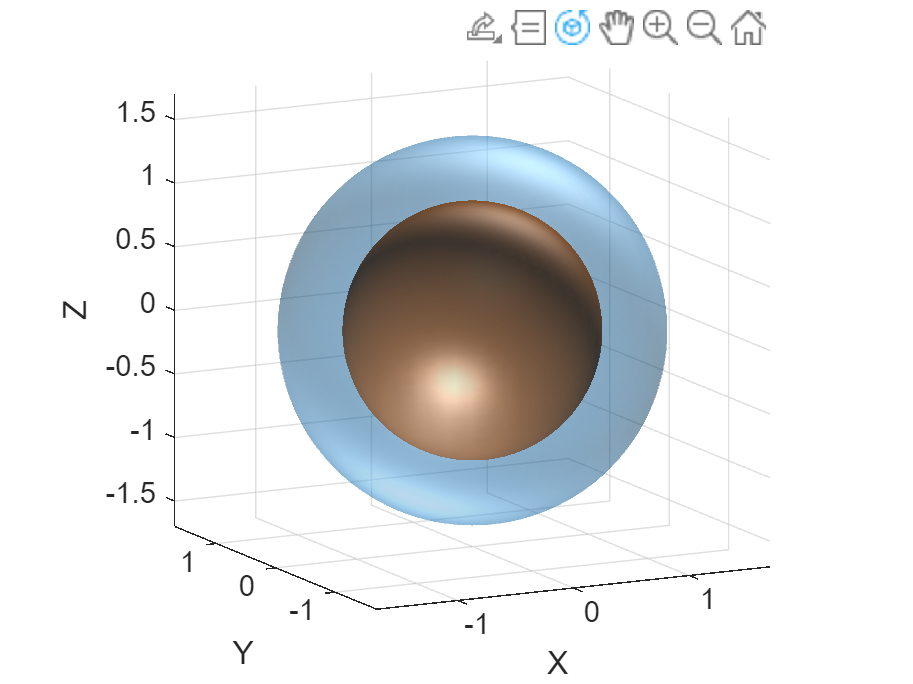

% 清除图形窗口和变量
clf;
clear;

% 创建一个新的图形窗口
figure('Color', 'white', 'Position', [100, 100, 800, 600]);

% 设置坐标系
axis equal;
grid on;
hold on;
xlabel('X');
ylabel('Y');
zlabel('Z');
% title('三维各向同性星体及球壳');

% 设置视角
view(3);

% 生成球体的网格数据
[theta, phi] = meshgrid(linspace(0, 2*pi, 50), linspace(0, pi, 50));

% 内部星体参数
R_inner = 1; % 内部星体半径

% 外部球壳参数
R_outer = 1.5; % 外部球壳半径
shell_thickness = 0.1; % 球壳厚度

% 计算笛卡尔坐标
x_inner = R_inner * sin(phi) .* cos(theta);
y_inner = R_inner * sin(phi) .* sin(theta);
z_inner = R_inner * cos(phi);

% 绘制内部星体（各向同性星体）
surf(x_inner, y_inner, z_inner, ...
    'FaceColor', [0.8, 0.4, 0.1], ... % 橙色
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.9, ...
    'AmbientStrength', 0.3, ...
    'DiffuseStrength', 0.8, ...
    'SpecularStrength', 0.5);

% 绘制外部球壳（半透明）
x_outer = R_outer * sin(phi) .* cos(theta);
y_outer = R_outer * sin(phi) .* sin(theta);
z_outer = R_outer * cos(phi);

surf(x_outer, y_outer, z_outer, ...
    'FaceColor', [0.1, 0.5, 0.8], ... % 蓝色
    'EdgeColor', 'none', ...
    'FaceAlpha', 0.3, ...
    'AmbientStrength', 0.4, ...
    'DiffuseStrength', 0.6, ...
    'SpecularStrength', 0.9);

% 添加光照效果
light('Position', [1, 1, 1], 'Style', 'infinite');
light('Position', [-1, -1, -1], 'Style', 'infinite');
lighting gouraud;

% 设置坐标轴范围
axis([-R_outer-0.2, R_outer+0.2, -R_outer-0.2, R_outer+0.2, -R_outer-0.2, R_outer+0.2]);

% 添加颜色条和图例
colormap(jet);
% colorbar;
% legend('各向同性星体', '外部球壳', 'Location', 'northeast');

% 旋转图形以便更好观察
rotate3d on;

% axis off